% FSI: 2DOF mechanical oscillator -Simulink
% Filip Kšica, VUT 2025

clc; close all; clear all

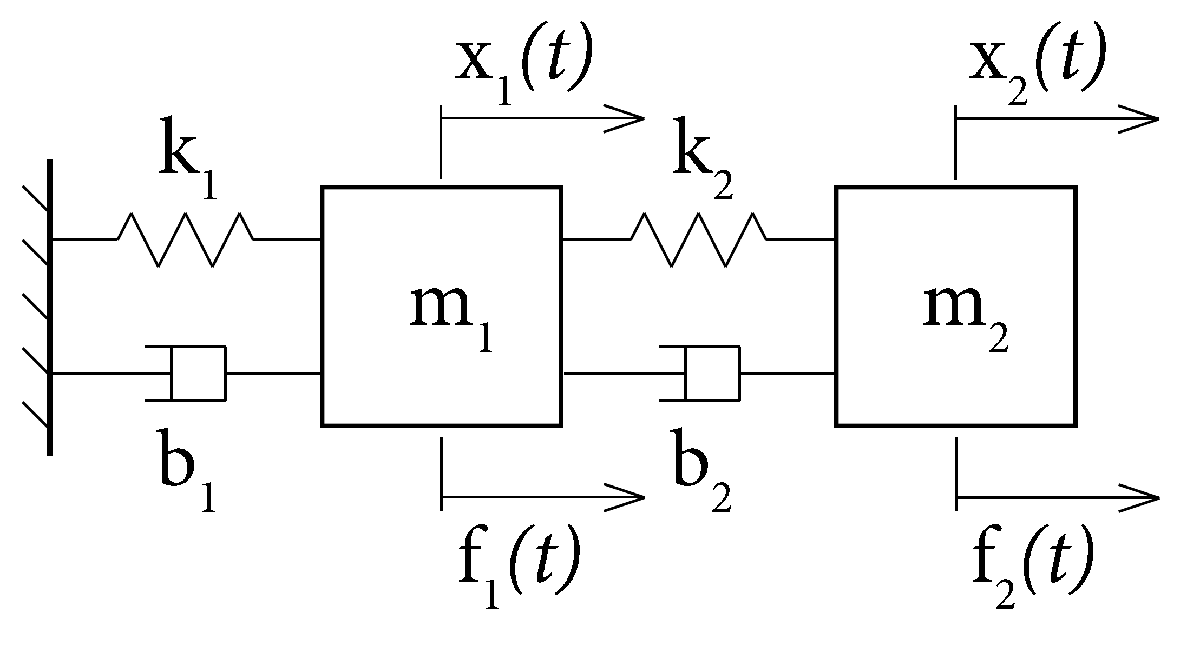

## Equations of motion:

Let's use d'Alembert principle to assemble equations of motion. Dynamic balance in force for 1DOF mass-spring-damper system is:


$$f_k \left(t\right)+f_b \left(t\right)+f_d \left(t\right)+f\left(t\right)=0$$


where $f_k \left(t\right)$ is the force applied by elastic spring, $f_b \left(t\right)$is the force applied by viscous damper and $f_d \left(t\right)$is the inertial force (d'Alembert force).


$$f_k \left(t\right)=\textrm{kx}$$
  
$$f_b \left(t\right)=b\dot{x}$$
  
$$f_d \left(t\right)=-m\ddot{x}$$


For 2DOF mass-spring-damper system, these two ODE describe the dynamic motion of the system (chosen direction of ***x*** is right):


$$-f_{\textrm{k1}} \left(t\right)+f_{\mathrm{k}2} \left(t\right)-f_{\textrm{b1}} \left(t\right)+f_{\mathrm{b}2} \left(t\right)+f_{\textrm{d1}} \left(t\right)-f_{\mathrm{d}2} \left(t\right)+f_1 \left(t\right)=0$$



$$-f_{\mathrm{k}2} \left(t\right)-f_{\mathrm{b}2} \left(t\right)+f_{\mathrm{d}2} \left(t\right)+f_2 \left(t\right)=0$$


Force terms are given as

 
$$f_{\textrm{k1}} \left(t\right)=k_1 x_1$$
  
$$f_{\textrm{b1}} \left(t\right)=b_1 {\dot{x} }_1$$
  
$$f_{\textrm{d1}} \left(t\right)=-m_1 \ddot{x_1 }$$


 
$$f_{\textrm{k2}} \left(t\right)=k_2 \left({x_2 -x}_1 \right)$$
  
$$f_{\mathrm{b}2} \left(t\right)=b_2 \left({\dot{x} }_2 -{\dot{x} }_1 \right)$$
  
$$f_{\mathrm{d}2} \left(t\right)=-m_2 \ddot{x_2 }$$


Substituting these terms into the base equation:


$${-m}_1 {\ddot{x} }_1 -b_1 {\dot{x} }_1 +b_2 \left({\dot{x} }_2 -{\dot{x} }_1 \right)-k_1 x_1 +k_2 \left({x_2 -x}_1 \right)+f_1 \left(t\right)=0$$



$${-m}_2 {\ddot{x} }_2 -b_2 \left({\dot{x} }_2 -{\dot{x} }_1 \right)-k_2 \left({x_2 -x}_1 \right)+f_2 \left(t\right)=0$$


After rearranging the terms:


$$m_1 {\ddot{x} }_1 +b_1 {\dot{x} }_1 -b_2 \left({\dot{x} }_2 -{\dot{x} }_1 \right)+k_1 x_1 -k_2 \left({x_2 -x}_1 \right)=f_1 \left(t\right)$$



$$m_2 {\ddot{x} }_2 +b_2 \left({\dot{x} }_2 -{\dot{x} }_1 \right)+k_2 \left({x_2 -x}_1 \right)=f_2 \left(t\right)$$


Isolating the individual states we get the final form:


$$m_1 {\ddot{x} }_1 +\left(b_1 +b_2 \right){\dot{x} }_1 -b_2 {\dot{x} }_2 +\left(k_1 +k_2 \right)x_1 -k_2 x_2 =f_1 \left(t\right)$$



$$m_2 {\ddot{x} }_2 +b_2 {\dot{x} }_2 -b_2 {\dot{x} }_1 +k_2 {x_2 -k_2 x}_1 =f_2 \left(t\right)$$


Form of equations suitable for Simulink:


$${\ddot{x} }_1 =\frac{1}{m_1 }\left\lbrack -\left(b_1 +b_2 \right){\dot{x} }_1 +b_2 {\dot{x} }_2 -\left(k_1 +k_2 \right)x_1 +k_2 x_2 +f_1 \left(t\right)\right\rbrack$$



$${\ddot{x} }_2 =\frac{1}{m_2 }\left\lbrack -b_2 {\dot{x} }_2 +b_2 {\dot{x} }_1 -k_2 {x_2 +k_2 x}_1 +f_2 \left(t\right)\right\rbrack$$


### The provided Simulink model works with these equations (just a rearranged form, do not panic!):


$${\ddot{x} }_1 =-\frac{b_1 }{m_1 }{\dot{x} }_1 -\frac{b_2 }{m_1 }\left({\dot{x} }_1 -{\dot{x} }_2 \right)-\frac{k_1 }{m_1 }x_1 -\frac{k_2 }{m_1 }\left({x_1 -x}_2 \right)+\frac{f_1 \left(t\right)}{m_1 }$$



$${\ddot{x} }_2 =\frac{b_2 }{m_2 }{\dot{x} }_1 -\frac{b_2 }{m_2 }{\dot{x} }_2 +\frac{k_2 }{m_2 }x_1 -\frac{k_2 }{m_2 }x_2 +\frac{f_2 }{m_2 }\left(t\right)$$


### The generalized eigenvalue problem is based on an equation of motion for free oscillations of nDOF system:


$$M\ddot{x} +\textrm{Kx}=0$$


where M is mass matrix and K is stifness matrix. Expected solution is in a form of $x=x_0 e^{i\omega t}$, where $0<\omega_1^2 <\cdots <\omega_n^2$ are the system's eigenvalues. Substituting into the abovementioned equation we finalize a form


$$\left(M^{-1} K-\Omega^2 E\right)x=0$$


There are numerous solution methods for a generalized eigenvalue problem (see [example](https://web.stanford.edu/group/frg/course_work/AA242B/CA-AA242B-Ch6.pdf)), but in Matlab we will use *eig* to obtain eigenvalues and eigenvectors.

## Input parameters:

m1 = 1700;         % [kg] mass 1
m2 = 8.5;      % [kg] mass 2
k1 = 42e4;       % [Nm-1] stiffness 1
k2 = 2.1e3;     % [Nm-1] stiffness 2
b1 = 1.5e2;     % [Nsm-1] damping 1
b2 = 1e-10;%5;      % [Nsm-1] damping 2

dt = 1e-3;      % [s] time step
t_start = 0;    % [s] initial time
t_end = 30;      % [s] end time    
t = t_start:dt:t_end; 

% m1 = 5;         % [kg] mass 1
% m2 = 1e-1;      % [kg] mass 2
% k1 = 8e4;       % [Nm-1] stiffness 1
% k2 = 1.6e3;     % [Nm-1] stiffness 2
% b1 = 2.5e1;     % [Nsm-1] damping 1
% b2 = 5e-1;      % [Nsm-1] damping 2
% 
% dt = 1e-4;      % [s] time step
% t_start = 0;    % [s] initial time
% t_end = 2;      % [s] end time    
% t = t_start:dt:t_end; 


### Separate systems

omega_01 = sqrt(k1/m1);
f_01 = omega_01/(2*pi);
xi_1 = b1/(2*m1*omega_01);
f_01d = f_01*sqrt(1-xi_1^2);
omega_02 = sqrt(k2/m2);
f_02 = omega_02/(2*pi);
xi_2 = b2/(2*m2*omega_02);
f_02d = f_02*sqrt(1-xi_2^2);

fprintf('Separate systems: \n')

Separate systems: 


fprintf('Dynamic properties of mass 1: \n')

Dynamic properties of mass 1: 


fprintf('Eigenfrequency (undamped): %.3f Hz \n',f_01)

Eigenfrequency (undamped): 2.502 Hz 


fprintf('Eigenfrequency (damped): %.3f Hz \n',f_01d)

Eigenfrequency (damped): 2.502 Hz 


fprintf('Damping ratio: %.2f \n',xi_1)

Damping ratio: 0.00 



fprintf('\nDynamic properties of mass 2: \n')


Dynamic properties of mass 2: 


fprintf('Eigenfrequency (undamped): %.3f Hz \n',f_02)

Eigenfrequency (undamped): 2.502 Hz 


fprintf('Eigenfrequency (damped): %.3f Hz \n',f_02d)

Eigenfrequency (damped): 2.502 Hz 


fprintf('Damping ratio: %.2f \n',xi_2)

Damping ratio: 0.00 


### Connected systems

M = [ m1 0; 0 m2 ]              % mass matrix

M = 1.0e+03 *

    1.7000         0
         0    0.0085


K = [ k1+k2 -k2 ; -k2 k2 ]      % stiffness matrix

K =       422100       -2100
       -2100        2100



A = inv(M)*K;                   

[X,L] = eig(A);                 % eigenvectors and eigenvalues
W = sqrt(L);                    % [rads-1] eigenfrequencies
F = W./(2*pi);                  % [Hz] eigenfrequencies
f0 = [F(1,1); F(2,2)];

fprintf('\n\nConnected systems: \n')



Connected systems: 


fprintf('1. Eigenfrequency (undamped): %.3f Hz \n',f0(1))

1. Eigenfrequency (undamped): 2.592 Hz 


fprintf('2. Eigenfrequency (undamped): %.3f Hz \n',f0(2))

2. Eigenfrequency (undamped): 2.415 Hz 


fprintf('1. Eigenvector: %.3f %.3f \n',X(1,1),X(2,1))

1. Eigenvector: 0.073 -0.997 


fprintf('2. Eigenvector: %.3f %.3f \n',X(1,2),X(2,2))

2. Eigenvector: 0.068 0.998 


## Initial condtitions

x10 = 0;      % [m]
dx10 = 0;     % [ms-1]
x20 = 0;      % [m]
dx20 = 0;     % [ms-1]

## Simulink simulation of separate and connected systems

joint_control = 1;  % joint control (0 = joint off, 1 = joint on)

pb_1 = 0;   % excitation of mass 1 (0 = impulse, 1 = harmonic)
f1_t = t;           % [s] time 

Unrecognized function or variable 't'.

f1_freq = omega_01;%*2*pi;  % [rad/s] frequency
f1_a = 1e4;         % [N] force amplitude
f1_fi = 0;          % [rad] phase shift
step_time_1 = 0;
step_width_1 = dt;

pb_2 = 0;       % excitation of mass 2 (0 = impulse, 1 = harmonic)
f2_t = t;           % [s] time 
f2_freq = omega_02;  % [rad/s] frequency
f2_a = 1e2;           % [N] force amplitude
f2_fi = 0;          % [rad] phase shift
step_time_2 = 0;
step_width_2 = dt;

for i = 1:2
    joint_control = i-1;
    if joint_control == 1
        f2_a = 0;        
    end
    
    sim('FSI_2DOF_sim',[t]); % initiate simulation in Simulink
    
    x1_sim(:,i) = simout(:,1);
    dx1_sim(:,i) = simout(:,2);
    x2_sim(:,i) = simout(:,3);
    dx2_sim(:,i) = simout(:,4);
end


## Plot results

### Time-domain impulse response

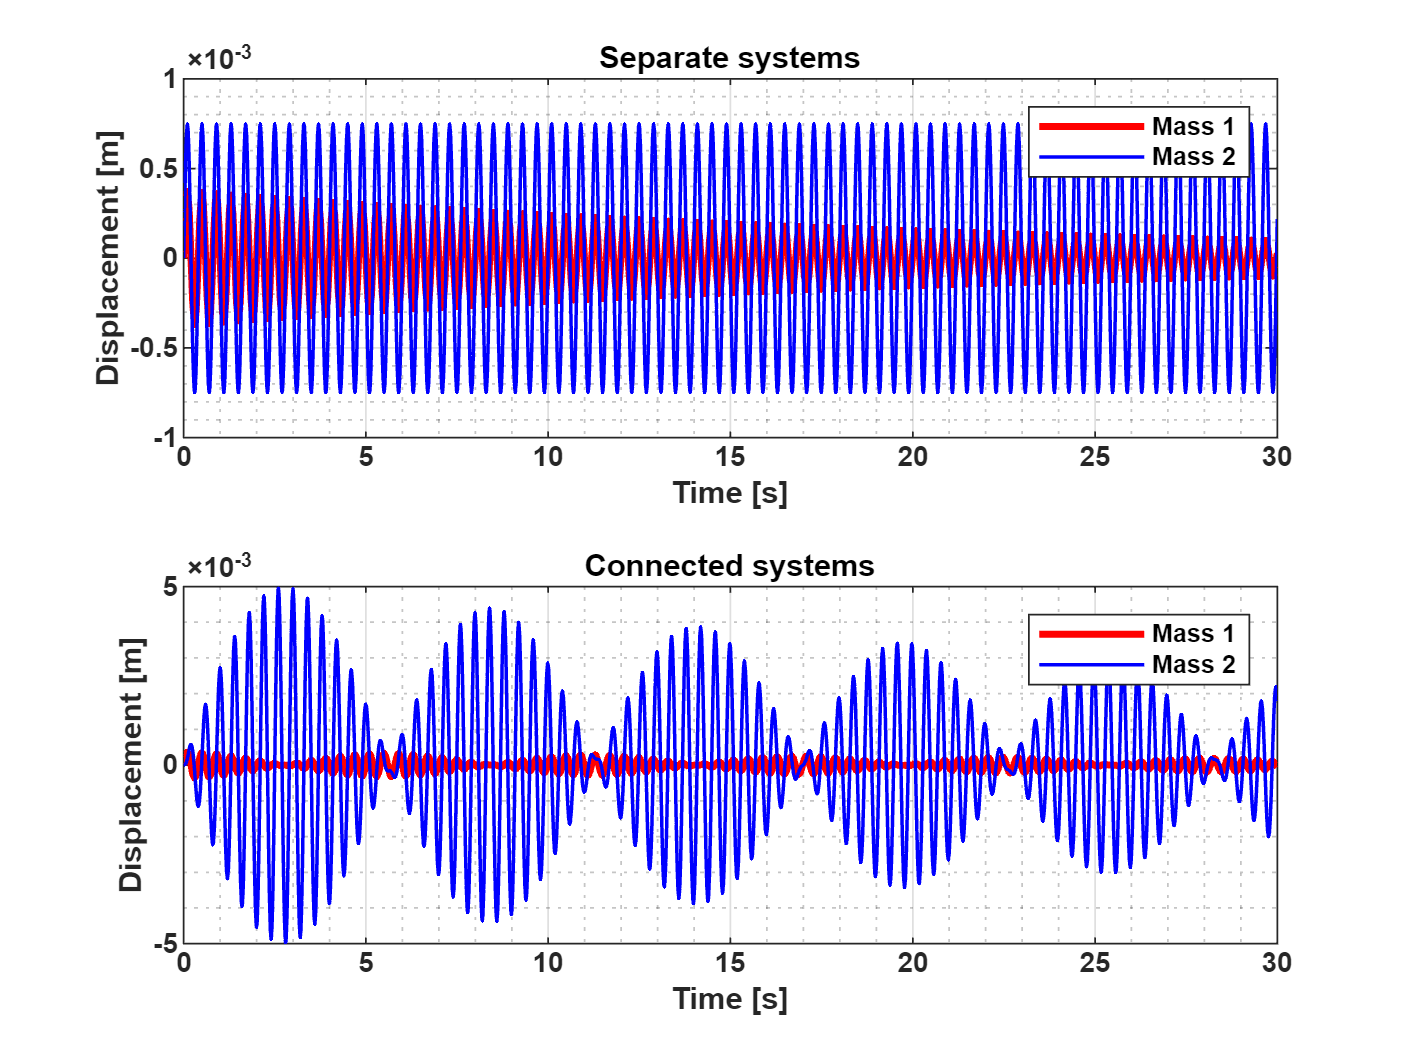

figure(1);set(gcf,'color','w')

tiledlayout(2,1)
nexttile
plot(t,x1_sim(:,1),'-r','LineWidth',2);hold on
plot(t,x2_sim(:,1),'-b','LineWidth',1)
grid on;grid minor
xlabel('Time [s]','FontSize',8)
ylabel('Displacement [m]','FontSize',8)
title('Separate systems','FontSize',8)
legend('Mass 1','Mass 2','Location','NorthEast')
set(findall(gcf, '-property', 'FontName'),'FontName','Arial')
set(findall(gcf, 'type','Axes'), 'FontSize', 8, 'FontWeight', 'bold')

nexttile
plot(t,x1_sim(:,2),'-r','LineWidth',2);hold on
plot(t,x2_sim(:,2),'-b','LineWidth',1)
grid on;grid minor
xlabel('Time [s]','FontSize',8)
ylabel('Displacement [m]','FontSize',8)
title('Connected systems','FontSize',8)
legend('Mass 1','Mass 2','Location','NorthEast')
set(findall(gcf, '-property', 'FontName'),'FontName','Arial')
set(findall(gcf, 'type','Axes'), 'FontSize', 8, 'FontWeight', 'bold')

### Frequency-domain impulse response

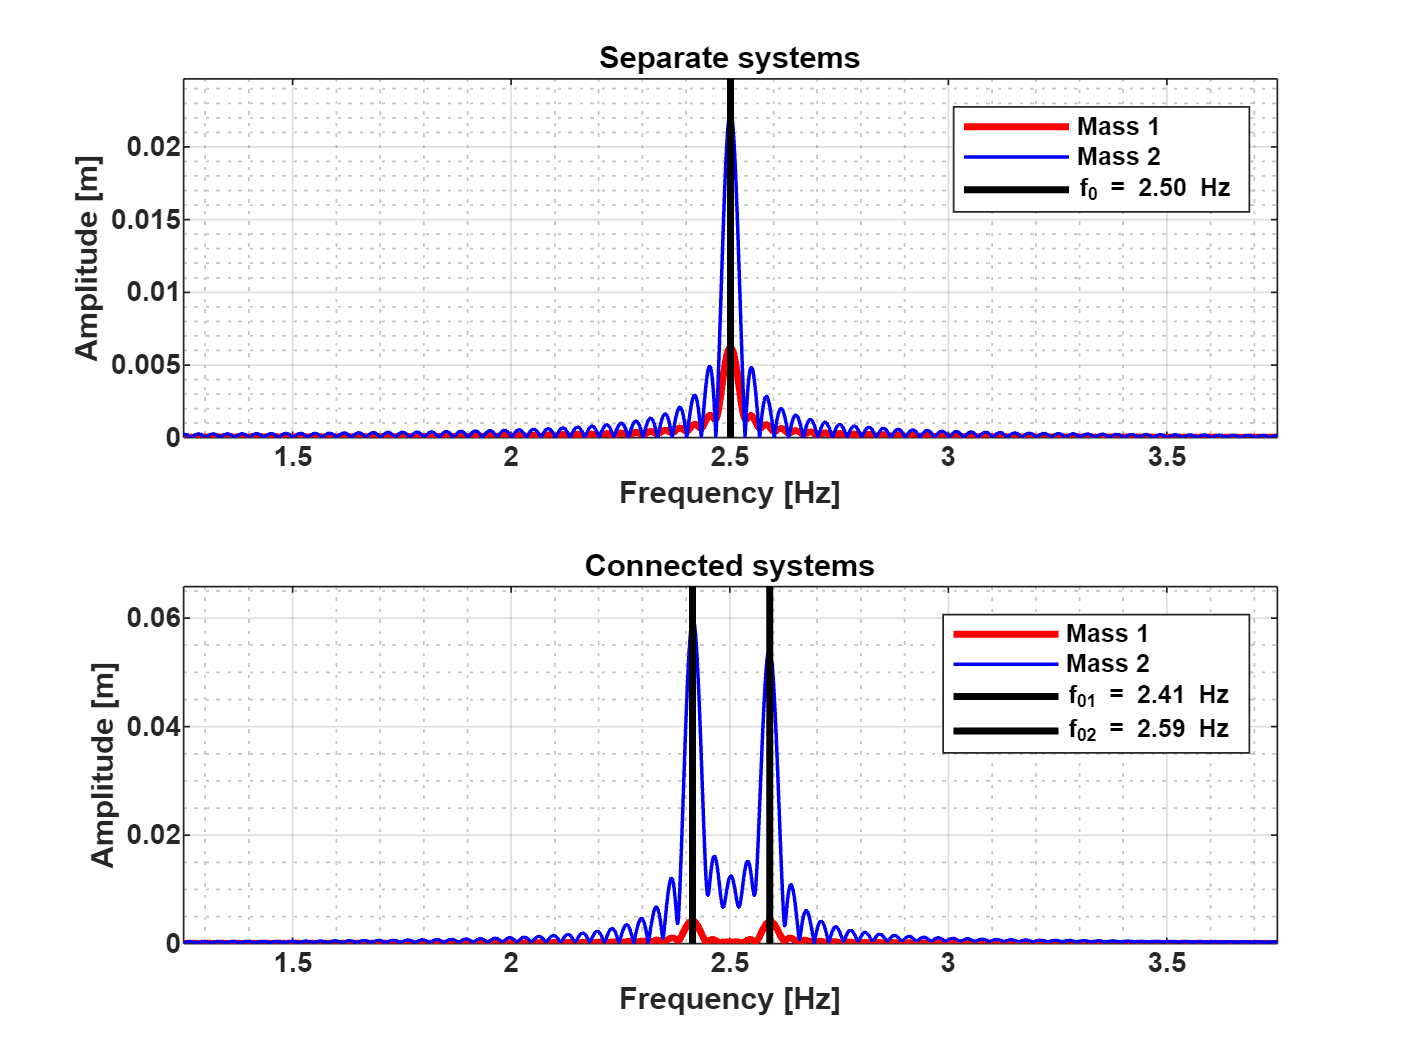

padding_length = 20*length(x1_sim(:,1));
fs = 1/dt;

for i = 1:2
    data1_padded = [x1_sim(:,i); zeros(padding_length,1)];
    data2_padded = [x2_sim(:,i); zeros(padding_length,1)];

    length_data1 = length(data1_padded);                  % [sample] length of signal 
    length_data2 = length(data2_padded);                  % [sample] length of signal 
    NFFT1 = 2^nextpow2(length_data1);                     % nearest 2^n to the length of the signal
    NFFT2 = 2^nextpow2(length_data2);                     % nearest 2^n to the length of the signal
    data1_fft = fft(data1_padded,NFFT1)/fs;
    data2_fft = fft(data2_padded,NFFT2)/fs;
    data1_fft2 = 2*abs(data1_fft(1:NFFT1/2+1));           % trimming of negative frequencies (it is symmetrical)
    data2_fft2 = 2*abs(data2_fft(1:NFFT2/2+1));           % trimming of negative frequencies (it is symmetrical)
    freq1 = linspace(0,fs/2,length(data1_fft2));          % x axis sampling
    freq2 = linspace(0,fs/2,length(data2_fft2));          % x axis sampling
    x1_fft(:,i) = data1_fft2;
    x2_fft(:,i) = data2_fft2;
end

figure(2);set(gcf,'color','w')
tiledlayout(2,1)
nexttile
plot(freq1,x1_fft(:,1),'-r','LineWidth',2);hold on
plot(freq2,x2_fft(:,1),'-b','LineWidth',1);
plot([f_01 f_01],[0 1.1*max([x1_fft(:,1); x2_fft(:,1)])],'-k','LineWidth',2);
plot([f_02 f_02],[0 1.1*max([x1_fft(:,1); x2_fft(:,1)])],'-k','LineWidth',2);
grid on; grid minor;
xlim([0.5*f_01 1.5*f_01])
ylim([0 1.1*max([x1_fft(:,1); x2_fft(:,1)])])
xlabel('Frequency [Hz]','FontSize',8)
ylabel('Amplitude [m]','FontSize',8)
title('Separate systems','FontSize',8)
str1 = sprintf('Mass 1'); str2 = sprintf('Mass 2'); str3 = sprintf('f_{0} = %.2f Hz', f_01);
legend(str1,str2,str3,'Location','NorthEast')

set(findall(gcf, '-property', 'FontName'),'FontName','Arial')
set(findall(gcf, 'type','Axes'), 'FontSize', 8, 'FontWeight', 'bold')

nexttile
plot(freq1,x1_fft(:,2),'-r','LineWidth',2);hold on
plot(freq2,x2_fft(:,2),'-b','LineWidth',1);
plot([min(f0) min(f0)],[0 1.1*max([x2_fft(:,2); x2_fft(:,2)])],'-k','LineWidth',2);
plot([max(f0) max(f0)],[0 1.1*max([x2_fft(:,2); x2_fft(:,2)])],'-k','LineWidth',2);
grid on; grid minor;
xlim([0.5*f_01 1.5*f_01])
ylim([0 1.1*max([x1_fft(:,2); x2_fft(:,2)])])
xlabel('Frequency [Hz]','FontSize',8)
ylabel('Amplitude [m]','FontSize',8)
title('Connected systems','FontSize',8)
str1 = sprintf('Mass 1'); str2 = sprintf('Mass 2'); str3 = sprintf('f_{01} = %.2f Hz', min(f0)); str4 = sprintf('f_{02} = %.2f Hz', max(f0));
legend(str1,str2,str3,str4,'Location','NorthEast')

set(findall(gcf, '-property', 'FontName'),'FontName','Arial')
set(findall(gcf, 'type','Axes'), 'FontSize', 8, 'FontWeight', 'bold')